clear all,clc;
% test3:
% marginal likelihood parameters v.s. maximum likelihood parameters
load('my_linear.mat')
cell_type = 1;
experiment_num =3;
total_num = (cell_type-1)*10 + experiment_num;

output(total_num).maximum_likelihood.parameters

ans = struct with fields:
       theta_pref: 210
               Rp: 5.5897
               Rn: 0
            sigma: 60
              Rsp: 5.8316
    tunning_curve: [360×1 double]

output(total_num).maximum_likelihood.descriptors

ans = struct with fields:
        di: 0.4840
        oi: 0.1980
        cv: 0.9893
    dir_cv: 0.8339

theta = 0:359;
marginal_theta_pref = output(total_num).marginal_likelihood.theta_pref.values(find(output(total_num).marginal_likelihood.theta_pref.likelihoods==max(output(total_num).marginal_likelihood.theta_pref.likelihoods)))

marginal_theta_pref = 290

marginal_rp = output(total_num).marginal_likelihood.Rp.values(find(output(total_num).marginal_likelihood.Rp.likelihoods==max(output(total_num).marginal_likelihood.Rp.likelihoods)))

marginal_rp = 0.7862

marginal_rn = marginal_rp * output(total_num).marginal_likelihood.Alpha.values(find(output(total_num).marginal_likelihood.Alpha.likelihoods==max(output(total_num).marginal_likelihood.Alpha.likelihoods)))

marginal_rn = 0.1123

marginal_sigma = output(total_num).marginal_likelihood.sigma.values(find(output(total_num).marginal_likelihood.sigma.likelihoods==max(output(total_num).marginal_likelihood.sigma.likelihoods)))

marginal_sigma = 5

marginal_rsp = output(total_num).marginal_likelihood.Rsp.values(find(output(total_num).marginal_likelihood.Rsp.likelihoods==max(output(total_num).marginal_likelihood.Rsp.likelihoods)))

marginal_rsp = 7.9158

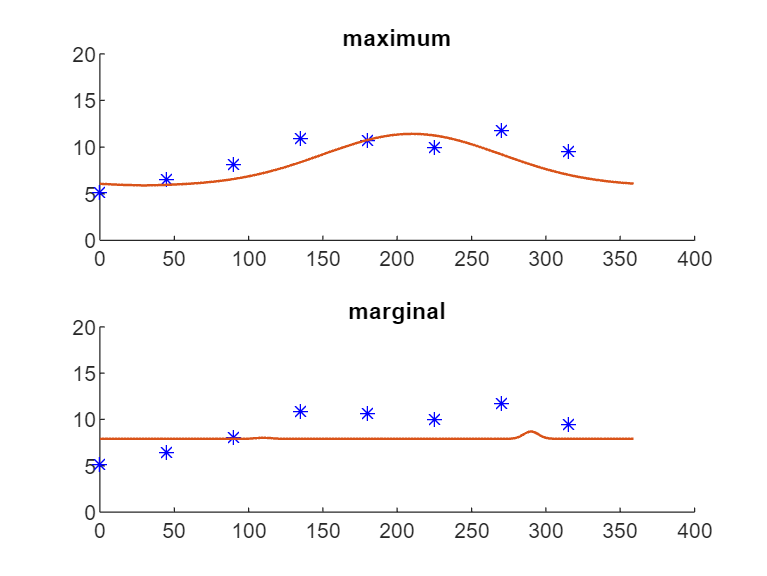

marginal_curve = marginal_rsp + marginal_rp * exp(-0.5*angdiff(theta-marginal_theta_pref).^2/marginal_sigma^2) + marginal_rn * exp(-0.5*angdiff(theta-marginal_theta_pref+180).^2/marginal_sigma^2);

%marginal parameters v.s. maximum parameters curve plotting
tiledlayout flow
nexttile
hold on
plot(data_mean{cell_type}(experiment_num).angle,data_mean{cell_type}(experiment_num).mean_responses,'b*')
plot(0:359,output(total_num).maximum_likelihood.parameters.tunning_curve,LineWidth=1)
ylim([0 20])
title('maximum')

nexttile
hold on
plot(data_mean{cell_type}(experiment_num).angle,data_mean{cell_type}(experiment_num).mean_responses,'b*')
plot(0:359,marginal_curve,LineWidth=1)
ylim([0 20])
title('marginal')

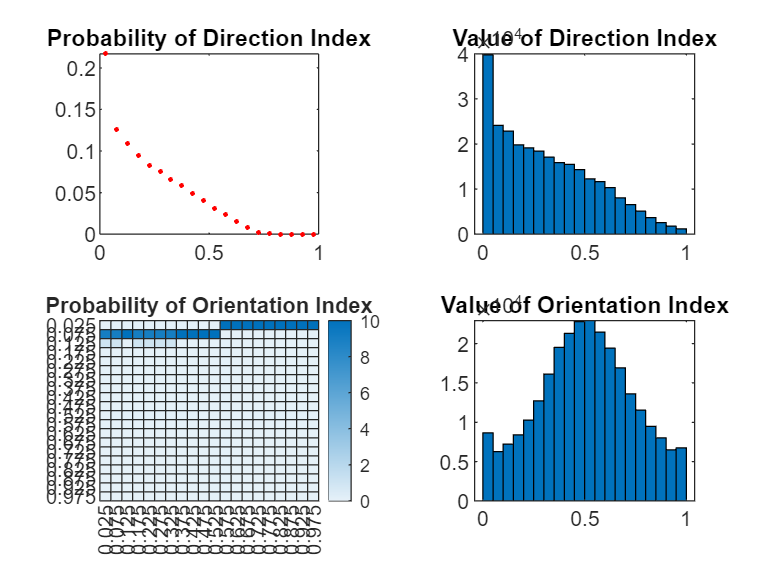

edges = 0:0.05:1;
center = edges(1:end-1) + (edges(1)+edges(2))/2;

% calculate heatmap 2-D matrix
% avg_lik: average of likelihood distribution of 10 curves
oi_lik_heatmap = zeros(length(edges)-1,length(output(1).descriptors.oi.histogram_count));
lik_heatmap = oi_lik_heatmap;
for total_num = 1:10
    oi_lik_index = discretize(output(total_num).descriptors.oi.histogram_likelihoods,edges);
    for oi_bin = 1:length(output(total_num).descriptors.oi.histogram_likelihoods)
        lik_heatmap(oi_lik_index(oi_bin),oi_bin) = 1;
    end
    oi_lik_heatmap = oi_lik_heatmap + lik_heatmap;
    lik_heatmap(:) = 0;
end

%plot
tiledlayout flow
nexttile
plot(center,output(1).descriptors.di.histogram_likelihoods,'r.')
title('Probability of Direction Index')

nexttile
bar(center,output(1).descriptors.di.histogram_count,1)
title('Value of Direction Index')

nexttile
heatmap(center,center,oi_lik_heatmap)
title('Probability of Orientation Index')

nexttile
bar(center,output(1).descriptors.oi.histogram_count,1)
title('Value of Orientation Index')

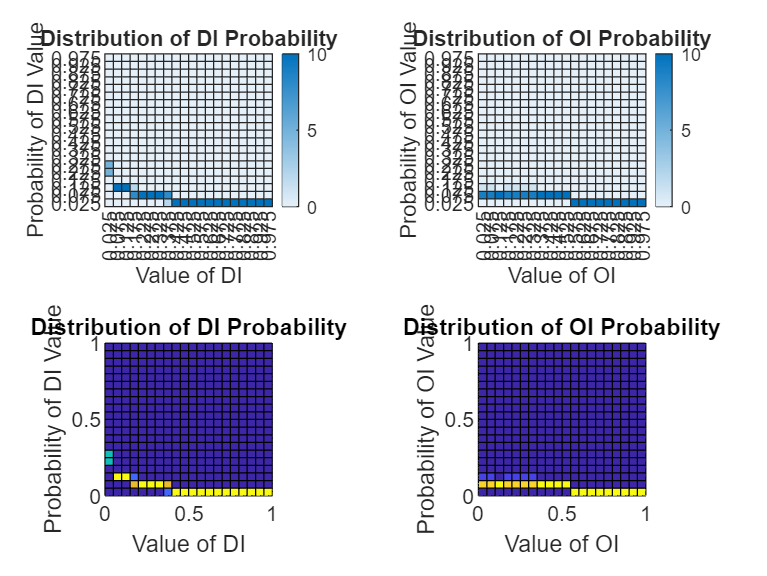

% DI_LIK_HEATMAP: describe the 2-D location in figures
% OI_LIK_HEATMAP: describe the 2-D location in figures
% LIK_HEATMAP: deliver each point of single curve to figure
oi_lik_heatmap = zeros(length(edges)-1,length(output(1).descriptors.oi.histogram_count));
di_lik_heatmap = zeros(length(edges)-1,length(output(1).descriptors.di.histogram_count));
lik_heatmap = oi_lik_heatmap;

for total_num = 1:10
    % calculate heatmap 2-D matrix
    di_lik_index = discretize(output(total_num).descriptors.di.histogram_likelihoods,edges);
    for di_bin = 1:length(output(total_num).descriptors.di.histogram_likelihoods)
        lik_heatmap(di_lik_index(di_bin),di_bin) = 1;
    end
    di_lik_heatmap = di_lik_heatmap + lik_heatmap;
    lik_heatmap(:) = 0;
end

for total_num = 1:10
    % calculate heatmap 2-D matrix
    oi_lik_index = discretize(output(total_num).descriptors.oi.histogram_likelihoods,edges);
    for oi_bin = 1:length(output(total_num).descriptors.oi.histogram_likelihoods)
        lik_heatmap(oi_lik_index(oi_bin),oi_bin) = 1;
    end
    oi_lik_heatmap = oi_lik_heatmap + lik_heatmap;
    lik_heatmap(:) = 0;
end

tiledlayout flow
nexttile,
heatmap(center,flip(center),flip(di_lik_heatmap,1))
xlabel('Value of DI')
ylabel('Probability of DI Value')
title('Distribution of DI Probability')

nexttile,
heatmap(center,flip(center),flip(oi_lik_heatmap,1))
xlabel('Value of OI')
ylabel('Probability of OI Value')
title('Distribution of OI Probability')

nexttile,
di_lik_pcolor = [di_lik_heatmap;zeros(1,length(output(total_num).descriptors.di.histogram_likelihoods))];
di_lik_pcolor = [di_lik_pcolor,zeros(length(edges),1)];
pcolor(edges,edges,di_lik_pcolor)
xlabel('Value of DI')
ylabel('Probability of DI Value')
title('Distribution of DI Probability')

nexttile,
oi_lik_pcolor = [oi_lik_heatmap;zeros(1,length(output(total_num).descriptors.oi.histogram_likelihoods))];
oi_lik_pcolor = [oi_lik_pcolor,zeros(length(edges),1)];
pcolor(edges,edges,oi_lik_pcolor)
xlabel('Value of OI')
ylabel('Probability of OI Value')
title('Distribution of OI Probability')

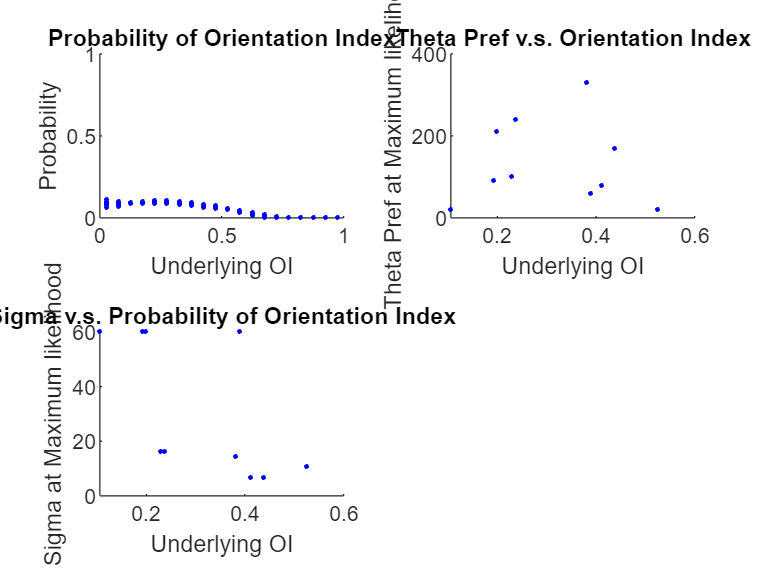

tiledlayout flow
nexttile,hold on
for total_num = 1:10
plot(.025:.05:1,output(total_num).descriptors.oi.histogram_likelihoods,'b.')
end
xlabel('Underlying OI')
ylabel('Probability')
ylim([0 1])
title('Probability of Orientation Index')

nexttile,hold on
for total_num = 1:10
    plot(output(total_num).maximum_likelihood.descriptors.oi,output(total_num).maximum_likelihood.parameters.theta_pref,'b.')
end
xlabel('Underlying OI')
ylabel('Theta Pref at Maximum likelihood')
title('Theta Pref v.s. Orientation Index')

nexttile,hold on
for total_num = 1:10
    plot(output(total_num).maximum_likelihood.descriptors.oi,output(total_num).maximum_likelihood.parameters.sigma,'b.')
end
xlabel('Underlying OI')
ylabel('Sigma at Maximum likelihood')
title('Sigma v.s. Probability of Orientation Index')